T = 10e-3; % length of the sequence (probe signal) in seconds
r = 10000; % rate
rolloff = 1/8;
fs = 1e6;
M = r*T;
Nsym = floor(T/M*fs)

Nsym = 100


figure('DefaultAxesFontSize',16);

% walsh code 
walsh = comm.WalshCode;
walsh.Length = 128;
walsh.SamplesPerFrame = M;
disp(walsh);

  comm.WalshCode with properties:

             Length: 128
              Index: 60
    SamplesPerFrame: 100
     OutputDataType: 'double'



wcode = walsh()

wcode =      1
     1
    -1
    -1
     1
     1
    -1
    -1
     1
     1




prbs = ltePRBS(7, M, "signed")

prbs =      1
    -1
     1
     1
     1
     1
    -1
     1
    -1
     1


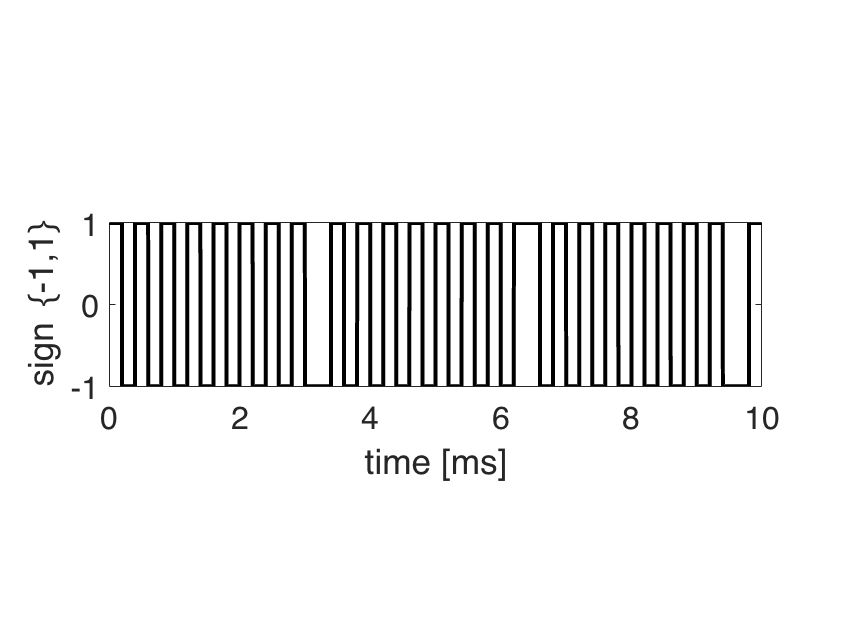

sig = [];

for m = 1:M
    sig = [sig wcode(m) * ones(1, Nsym)];
end




n = size(sig, 2);
time = linspace(0, n * 1000 / fs, n);
plot(time, sig, "k", "LineWidth",2);
xlabel("time [ms]");
ylabel("sign \{-1,1\}");
pbaspect([4 1 1]);

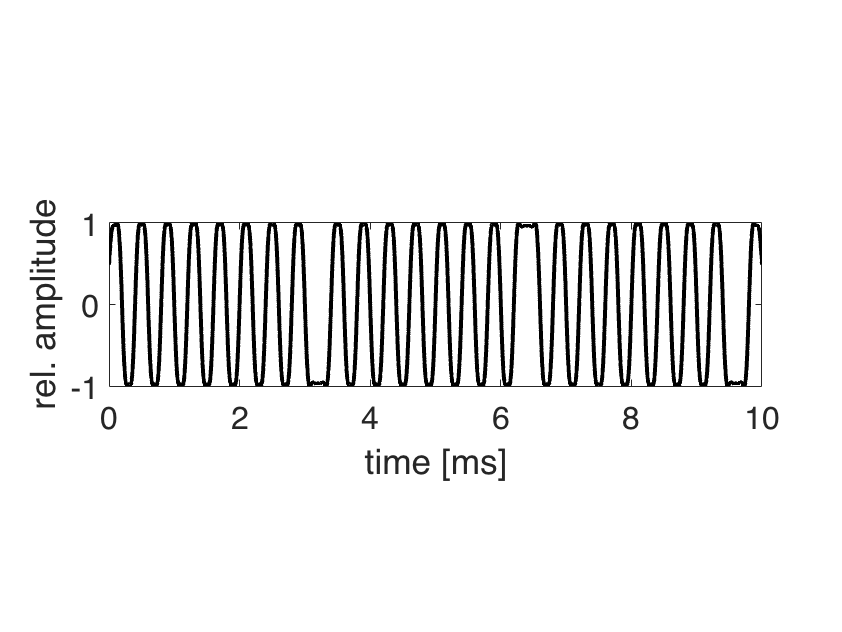


c = rcosdesign(1, 4*Nsym,Nsym);
delay = floor(length(c) / 2);
sig = [sig zeros(1,delay)];
%plot(time,sig)
sig = filter(c, 1, sig);
sig = sig(delay + 1:end);
plot(time,sig / max(abs(sig)),"k", "LineWidth",2)
xlabel("time [ms]");
ylabel("rel. amplitude");
pbaspect([4 1 1]);